clear variables
load('Tests/e1_coupled_tline/coupled_tl_28par_10std.mat')
[~,d] = size(training_samples);


training_samples = training_samples(1:870,:);
vouts_train = vouts_train(1:870,:);
m = 2;

tic
vouts_total2 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total2-vouts,"fro")/norm(vouts,"fro")

ans = 0.0299

toc

Elapsed time is 1.725228 seconds.


training_samples = training_samples2(1:8990,:);
vouts_train = vouts_train2(1:8990,:);
m = 3;

tic
vouts_total3 = pc_collocation_total(training_samples,vouts_train,samples,m ,'Hermite');
norm(vouts_total3-vouts,"fro")/norm(vouts,"fro")

ans = 0.0130

toc

Elapsed time is 37.151354 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_Newton,PC_coefficients_TT,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-Newton',0.3,0.2,r);

ans =     0.0040    0.0048   11.0000


ans =     0.0036    0.0045    2.0000


ans =     0.0036    0.0043    2.0000


ans =     0.0037    0.0043    2.0000


ans =     0.0037    0.0037    2.0000


ans =     0.0038    0.0040    2.0000


ans =     0.0039    0.0046    2.0000


ans =     0.0038    0.0049    2.0000


ans =     0.0036    0.0040    2.0000


ans =     0.0042    0.0044    2.0000


ans =     0.0033    0.0039    3.0000


ans =     0.0041    0.0050    2.0000


ans =     0.0040    0.0043    2.0000


ans =     0.0036    0.0039    2.0000


ans =     0.0036    0.0044    2.0000


ans =     0.0031    0.0037    3.0000


ans =     0.0037    0.0049    2.0000


ans =     0.0029    0.0039    3.0000


ans =     0.0035    0.0045    2.0000


ans =     0.0034    0.0041    3.0000


ans =     0.0037    0.0044    3.0000


ans =     0.0041    0.0047    3.0000


ans =     0.0035    0.0042    4.0000


ans =     0.0035    0.0046    4.0000


ans =     0.0032    0.0047    4.0000


ans =     0.0034    0.0047    3.0000


ans =     0.0039    0.0048    2.0000


ans =     0.0038    0.0047    3.0000


ans =     0.0033    0.0040    4.0000


ans =     0.0046    0.0048    2.0000


ans =     0.0039    0.0048    4.0000


ans =     0.0034    0.0048    6.0000


ans =     0.0037    0.0047    4.0000


ans =     0.0034    0.0047    4.0000


ans =     0.0028    0.0049    5.0000


ans =     0.0030    0.0045    4.0000


ans =     0.0035    0.0049    3.0000


ans =     0.0033    0.0049    4.0000


ans =     0.0028    0.0048    7.0000


ans =     0.0028    0.0049    8.0000


ans =     0.0026    0.0054   15.0000


ans =     0.0019    0.0055   18.0000


ans =     0.0018    0.0052   12.0000


ans =     0.0018    0.0050    8.0000


ans =     0.0019    0.0047    6.0000


ans =     0.0020    0.0049    5.0000


ans =     0.0018    0.0050    8.0000


ans =     0.0017    0.0050   12.0000


ans =     0.0018    0.0051   12.0000


ans =     0.0019    0.0049    6.0000


ans = 1×3
    0.0022    0.0049    4.0000


ans = 1×3
    0.0024    0.0049    4.0000


ans = 1×3
    0.0024    0.0050    6.0000


ans = 1×3
    0.0018    0.0051   13.0000


ans = 1×3
    0.0018    0.0051   12.0000


ans = 1×3
    0.0018    0.0050   12.0000


ans = 1×3
    0.0018    0.0050   12.0000


ans = 1×3
    0.0017    0.0051   12.0000


ans = 1×3
    0.0018    0.0055   12.0000


ans = 1×3
    0.0022    0.0061   13.0000


ans = 1×3
    0.0027    0.0075   13.0000


ans = 1×3
    0.0028    0.0078   13.0000


ans = 1×3
    0.0026    0.0071   13.0000


ans = 1×3
    0.0027    0.0067   11.0000


ans = 1×3
    0.0027    0.0069   13.0000


ans = 1×3
    0.0028    0.0078   13.0000


ans = 1×3
    0.0030    0.0089   15.0000


ans = 1×3
    0.0035    0.0103   15.0000


ans = 1×3
    0.0034    0.0102   13.0000


ans = 1×3
    0.0031    0.0088   13.0000


ans = 1×3
    0.0032    0.0081   13.0000


ans = 1×3
    0.0031    0.0080   12.0000


ans = 1×3
    0.0029    0.0077   12.0000


ans = 1×3
    0.0029    0.0073   12.0000


ans = 1×3
    0.0033    0.0080   13.0000


ans = 1×3
    0.0035    0.0089   13.0000


ans = 1×3
    0.0040    0.0105   13.0000


ans = 1×3
    0.0048    0.0136   12.0000


ans = 1×3
    0.0057    0.0167   13.0000


ans = 1×3
    0.0067    0.0173   13.0000


ans = 1×3
    0.0061    0.0161   17.0000


ans = 1×3
    0.0045    0.0131   16.0000


ans = 1×3
    0.0035    0.0097   15.0000


ans = 1×3
    0.0034    0.0094   13.0000


ans = 1×3
    0.0041    0.0108   15.0000


ans = 1×3
    0.0059    0.0140   14.0000


ans = 1×3
    0.0067    0.0162   13.0000


ans = 1×3
    0.0057    0.0149   16.0000


ans = 1×3
    0.0061    0.0161   16.0000


ans = 1×3
    0.0076    0.0208   15.0000


ans = 1×3
    0.0070    0.0205   16.0000


ans = 1×3
    0.0054    0.0148   15.0000


ans = 1×3
    0.0049    0.0124   12.0000


ans = 1×3
    0.0050    0.0133   12.0000


ans = 1×3
    0.0050    0.0160   17.0000


ans = 1×3
    0.0061    0.0193   15.0000


ans = 1×3
    0.0099    0.0255   15.0000


ans = 1×3
    0.0150    0.0314   15.0000


ans = 1×3
    0.0164    0.0335   16.0000


ans = 1×3
    0.0129    0.0295   15.0000


norm(vouts_Newton-vouts,"fro")/norm(vouts,"fro")

ans = 0.0114

toc

Elapsed time is 61.211542 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;

N = (m+1)*ones(d,1);
r = 3;
x = TTrand(N,r);
x{1}(1,:) = [1 zeros(1,r-1)];
for i = 1:d-1
    x{i}(1:r,:)=eye(r);
end
x{d}(1:r) = [vouts_train(1,1); zeros(r-1,1)];

tic
 [vouts_ALS,PC_coefficients_ALS,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-ALS',0.3,0.2,r);

ans = 1×3
    0.0021    0.0059  305.0000


ans = 1×3
    0.0019    0.0050  106.0000


ans = 1×3
    0.0023    0.0067   88.0000


ans = 1×3
    0.0022    0.0066   88.0000


ans = 1×3
    0.0021    0.0058   88.0000


ans = 1×3
    0.0021    0.0049   96.0000


ans = 1×3
    0.0024    0.0058   88.0000


ans = 1×3
    0.0024    0.0063   88.0000


ans = 1×3
    0.0017    0.0050  135.0000


ans = 1×3
    0.0023    0.0066  115.0000


ans = 1×3
    0.0022    0.0066  169.0000


ans = 1×3
    0.0021    0.0066  169.0000


ans = 1×3
    0.0016    0.0050  207.0000


ans = 1×3
    0.0018    0.0050  130.0000


ans = 1×3
    0.0023    0.0064   88.0000


ans = 1×3
    0.0019    0.0058  142.0000


ans = 1×3
    0.0017    0.0055  142.0000


ans = 1×3
    0.0018    0.0055  115.0000


ans = 1×3
    0.0021    0.0064   88.0000


ans = 1×3
    0.0023    0.0071   88.0000


ans = 1×3
    0.0029    0.0093   88.0000


ans = 1×3
    0.0025    0.0082  170.0000


ans = 1×3
    0.0024    0.0076  224.0000


ans = 1×3
    0.0024    0.0074  224.0000


ans = 1×3
    0.0026    0.0084  142.0000


ans = 1×3
    0.0029    0.0090   88.0000


ans = 1×3
    0.0029    0.0086   87.0000


ans = 1×3
    0.0022    0.0063  141.0000


ans = 1×3
    0.0020    0.0054  142.0000


ans = 1×3
    0.0023    0.0062  142.0000


ans = 1×3
    0.0029    0.0067  169.0000


ans = 1×3
    0.0027    0.0062  196.0000


ans = 1×3
    0.0022    0.0056  196.0000


ans = 1×3
    0.0023    0.0063  142.0000


ans = 1×3
    0.0021    0.0055  169.0000


ans = 1×3
    0.0021    0.0052  169.0000


ans = 1×3
    0.0021    0.0056  196.0000


ans = 1×3
    0.0024    0.0062  196.0000


ans = 1×3
    0.0030    0.0079  142.0000


ans = 1×3
    0.0033    0.0082  142.0000


ans = 1×3
    0.0035    0.0088  142.0000


ans = 1×3
    0.0035    0.0087  196.0000


ans = 1×3
    0.0040    0.0103  196.0000


ans = 1×3
    0.0039    0.0111  196.0000


ans = 1×3
    0.0035    0.0100  169.0000


ans = 1×3
    0.0031    0.0091  169.0000


ans = 1×3
    0.0029    0.0083  223.0000


ans = 1×3
    0.0031    0.0095  250.0000


ans = 1×3
    0.0038    0.0107  196.0000


ans = 1×3
    0.0033    0.0082  250.0000


ans = 1×3
    0.0029    0.0078  196.0000


ans = 1×3
    0.0031    0.0086  142.0000


ans = 1×3
    0.0033    0.0089  169.0000


ans = 1×3
    0.0035    0.0094  169.0000


ans = 1×3
    0.0027    0.0076  250.0000


ans = 1×3
    0.0028    0.0079  169.0000


ans = 1×3
    0.0029    0.0077  196.0000


ans = 1×3
    0.0031    0.0091  196.0000


ans = 1×3
    0.0028    0.0099  277.0000


ans = 1×3
    0.0038    0.0125  222.0000


ans = 1×3
    0.0041    0.0121  276.0000


ans = 1×3
    0.0042    0.0118  221.0000


ans = 1×3
    0.0036    0.0103  223.0000


ans = 1×3
    0.0038    0.0106  169.0000


ans = 1×3
    0.0043    0.0114  169.0000


ans = 1×3
    0.0042    0.0108  223.0000


ans = 1×3
    0.0039    0.0107  277.0000


ans = 1×3
    0.0046    0.0124  213.0000


ans = 1×3
    0.0046    0.0135  196.0000


ans = 1×3
    0.0040    0.0138  211.0000


ans = 1×3
    0.0042    0.0148  210.0000


ans = 1×3
    0.0037    0.0120  261.0000


ans = 1×3
    0.0036    0.0105  223.0000


ans = 1×3
    0.0038    0.0104  223.0000


ans = 1×3
    0.0039    0.0113  251.0000


ans = 1×3
    0.0038    0.0118  286.0000


ans = 1×3
    0.0043    0.0135  251.0000


ans = 1×3
    0.0051    0.0170  264.0000


ans = 1×3
    0.0061    0.0196  274.0000


ans = 1×3
    0.0073    0.0205  261.0000


ans = 1×3
    0.0080    0.0224  221.0000


ans = 1×3
    0.0062    0.0180  277.0000


ans = 1×3
    0.0050    0.0133  223.0000


ans = 1×3
    0.0045    0.0112  196.0000


ans = 1×3
    0.0050    0.0120  277.0000


ans = 1×3
    0.0071    0.0182  253.0000


ans = 1×3
    0.0073    0.0183  321.0000


ans = 1×3
    0.0066    0.0175  250.0000


ans = 1×3
    0.0071    0.0211  217.0000


ans = 1×3
    0.0084    0.0258  267.0000


ans = 1×3
    0.0082    0.0238  219.0000


ans = 1×3
    0.0059    0.0171  304.0000


ans = 1×3
    0.0050    0.0149  223.0000


ans = 1×3
    0.0051    0.0165  222.0000


ans = 1×3
    0.0063    0.0204  223.0000


ans = 1×3
    0.0086    0.0299  212.0000


ans = 1×3
    0.0146    0.0458  160.0000


ans = 1×3
    0.0181    0.0440  199.0000


ans = 1×3
    0.0183    0.0356  209.0000


ans = 1×3
    0.0148    0.0355  209.0000


norm(vouts_ALS-vouts,"fro")/norm(vouts,"fro")

ans = 0.0141

toc

Elapsed time is 126.679074 seconds.


training_samples = training_samples(1:660,:);
vouts_train = vouts_train(1:660,:);
m = 3;
r = 8;
x = cell(d,1);
for i = 1:d
    x{i} = zeros(m+1,1);
end


tic
 [vouts_GD,PC_coefficients_GD,training_err,test_err,n_iterations] = ...
     pc_collocation_tensor_optimization(training_samples,vouts_train,x,samples,m,'Hermite','TT-SGD',0.3,0.2,r,60,15);

ans = 1×3
    0.0004    0.0062  150.0000


ans = 1×3
    0.0005    0.0071  150.0000


ans = 1×3
    0.0005    0.0076  150.0000


ans = 1×3
    0.0004    0.0066  150.0000


ans = 1×3
    0.0004    0.0090  150.0000


ans = 1×3
    0.0005    0.0074  150.0000


ans = 1×3
    0.0005    0.0080  150.0000


ans = 1×3
    0.0004    0.0086  150.0000


ans = 1×3
    0.0004    0.0073  143.0000


ans = 1×3
    0.0005    0.0061  150.0000


ans = 1×3
    0.0005    0.0082  150.0000


ans = 1×3
    0.0006    0.0079  150.0000


ans = 1×3
    0.0006    0.0077  150.0000


ans = 1×3
    0.0006    0.0077  150.0000


ans = 1×3
    0.0006    0.0066  150.0000


ans = 1×3
    0.0005    0.0080  150.0000


ans = 1×3
    0.0005    0.0069  150.0000


ans = 1×3
    0.0006    0.0092  150.0000


ans = 1×3
    0.0005    0.0071  150.0000


ans = 1×3
    0.0006    0.0074  150.0000


ans = 1×3
    0.0006    0.0077  150.0000


ans = 1×3
    0.0006    0.0091  150.0000


ans = 1×3
    0.0006    0.0099  150.0000


ans = 1×3
    0.0006    0.0092  150.0000


ans = 1×3
    0.0006    0.0099  150.0000


ans = 1×3
    0.0008    0.0088  143.0000


ans = 1×3
    0.0005    0.0084  150.0000


ans = 1×3
    0.0006    0.0075  150.0000


ans = 1×3
    0.0007    0.0077  150.0000


ans = 1×3
    0.0006    0.0082  150.0000


ans = 1×3
    0.0007    0.0101  150.0000


ans = 1×3
    0.0007    0.0095  150.0000


ans = 1×3
    0.0007    0.0103  150.0000


ans = 1×3
    0.0007    0.0115  150.0000


ans = 1×3
    0.0007    0.0103  150.0000


ans = 1×3
    0.0007    0.0107  150.0000


ans = 1×3
    0.0008    0.0113  150.0000


ans = 1×3
    0.0008    0.0107  150.0000


ans = 1×3
    0.0012    0.0123  128.0000


ans = 1×3
    0.0009    0.0098  150.0000


ans = 1×3
    0.0009    0.0111  150.0000


ans = 1×3
    0.0009    0.0130  150.0000


ans = 1×3
    0.0011    0.0134  150.0000


ans = 1×3
    0.0011    0.0155  150.0000


ans = 1×3
    0.0008    0.0121  150.0000


ans = 1×3
    0.0010    0.0117  150.0000


ans = 1×3
    0.0009    0.0117  150.0000


ans = 1×3
    0.0014    0.0211   95.0000


ans = 1×3
    0.0021    0.0270   99.0000


ans = 1×3
    0.0017    0.0184  150.0000


ans = 1×3
    0.0014    0.0168  139.0000


ans = 1×3
    0.0017    0.0194  136.0000


ans = 1×3
    0.0018    0.0212  119.0000


ans = 1×3
    0.0014    0.0170  150.0000


ans = 1×3
    0.0012    0.0177  150.0000


ans = 1×3
    0.0009    0.0171  150.0000


ans = 1×3
    0.0013    0.0165   87.0000


ans = 1×3
    0.0011    0.0147  150.0000


ans = 1×3
    0.0014    0.0190  150.0000


ans = 1×3
    0.0018    0.0238  123.0000


ans = 1×3
    0.0027    0.0323  110.0000


ans = 1×3
    0.0030    0.0376  109.0000


ans = 1×3
    0.0028    0.0309  119.0000


ans = 1×3
    0.0030    0.0340  119.0000


ans = 1×3
    0.0020    0.0249  150.0000


ans = 1×3
    0.0015    0.0228  150.0000


ans = 1×3
    0.0018    0.0257  141.0000


ans = 1×3
    0.0025    0.0351  142.0000


ans = 1×3
    0.0028    0.0374  127.0000


ans = 1×3
    0.0034    0.0427  100.0000


ans = 1×3
    0.0030    0.0473  115.0000


ans = 1×3
    0.0030    0.0399  150.0000


ans = 1×3
    0.0026    0.0365  134.0000


ans = 1×3
    0.0035    0.0393   99.0000


ans = 1×3
    0.0032    0.0398  100.0000


ans = 1×3
    0.0042    0.0491   95.0000


ans = 1×3
    0.0043    0.0484   98.0000


ans = 1×3
    0.0039    0.0512   97.0000


ans = 1×3
    0.0031    0.0558  104.0000


ans = 1×3
    0.0039    0.0444  131.0000


ans = 1×3
    0.0033    0.0449  150.0000


ans = 1×3
    0.0030    0.0353  113.0000


ans = 1×3
    0.0019    0.0288  150.0000


ans = 1×3
    0.0019    0.0288  142.0000


ans = 1×3
    0.0039    0.0440  102.0000


ans = 1×3
    0.0052    0.0607  116.0000


ans = 1×3
    0.0056    0.0748  117.0000


ans = 1×3
    0.0059    0.0574  150.0000


ans = 1×3
    0.0064    0.0677  108.0000


ans = 1×3
    0.0089    0.1164   55.0000


ans = 1×3
    0.0056    0.0713  108.0000


ans = 1×3
    0.0051    0.0544   99.0000


ans = 1×3
    0.0034    0.0402  119.0000


ans = 1×3
    0.0031    0.0352  150.0000


ans = 1×3
    0.0031    0.0381  150.0000


ans = 1×3
    0.0028    0.0482  149.0000


ans = 1×3
    0.0043    0.0624  150.0000


ans = 1×3
    0.0063    0.0909  150.0000


ans = 1×3
    0.0079    0.0971  139.0000


ans = 1×3
    0.0071    0.0878  150.0000


norm(vouts_GD-vouts,"fro")/norm(vouts,"fro")

ans = 0.0343

toc

Elapsed time is 257.494864 seconds.


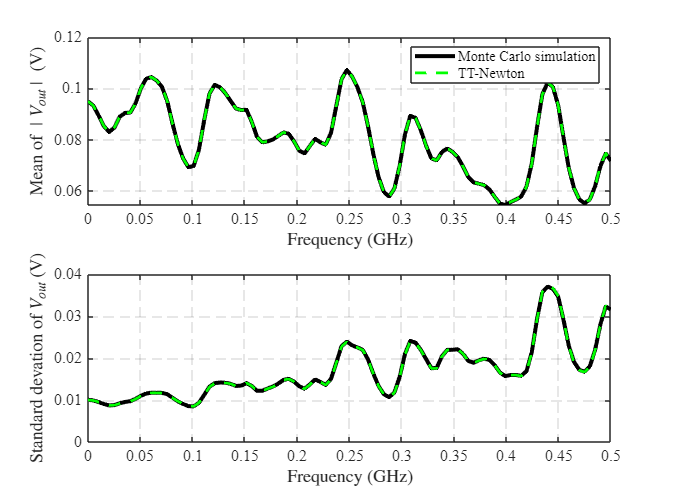

vout_mean0 = mean(abs(vouts));
vout_sigma0 = std((vouts));

vout_mean1 = mean(abs(vouts_Newton));
vout_sigma1 = std((vouts_Newton));


fpoints = linspace(0,5e8,100);
scale = 1e9;
f = figure(2);
subplot(2,1,1);
hold on
plot(fpoints/scale,vout_mean0,'k-','LineWidth',3);
plot(fpoints/scale,vout_mean1,'g--','LineWidth',2);
legend('Monte Carlo simulation','TT-Newton')
grid on
xlabel('Frequency (GHz)','interpreter','LaTex')
ylabel('Mean of $ \mid V_{out} \mid $ (V)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;


subplot(2,1,2);
hold on
plot(fpoints/scale,vout_sigma0,'k-','LineWidth',3);
plot(fpoints/scale,vout_sigma1,'g--','LineWidth',2);
ylim([0.0 0.04])
grid on
ylabel('Standard devation of $ V_{out} $ (V)','interpreter','LaTex')
xlabel('Frequency (GHz)','interpreter','LaTex')
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
set(gca,'FontSize',12)
box on;

f.Position = [100 100 675 500];

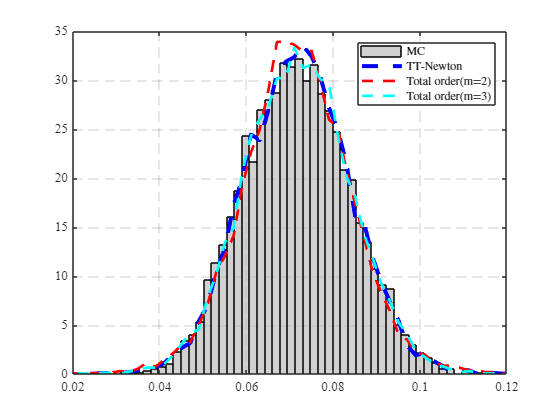

pdf_freq_idx = 100;
figure(1)
histogram(abs(vouts(:,pdf_freq_idx)),50,'Normalization','pdf', 'DisplayStyle','bar', 'FaceColor',[0.7 0.7 0.7]);
hold on
grid on
[N,edges] = histcounts(abs(vouts_Newton(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'b--','LineWidth',3)
[N,edges] = histcounts(abs(vouts_total2(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'r--','LineWidth',2)
[N,edges] = histcounts(abs(vouts_total3(:,pdf_freq_idx)), 'Normalization', 'pdf');
plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'c--','LineWidth',2)
% [N,edges] = histcounts(abs(vouts_GD(:,pdf_freq_idx)), 'Normalization', 'pdf');
% plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
% [N,edges] = histcounts(abs(vouts_ALS(:,pdf_freq_idx)), 'Normalization', 'pdf');
% plot(edges(1:end-1)+(edges(2)-edges(1))/2,N,'--','LineWidth',2)
xlim([0.02 0.12])
set(gca,'GridLineStyle','--')
set(gca, 'FontName', 'Times New Roman')
legend('MC', 'TT-Newton','Total order(m=2)','Total order(m=3)','interpreter','LaTex');